% initSim
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


L_f = l_f*Lbase1v

L_f = 2.5397e-07

R_f = r_f*Zbase1v

R_f = 3.9893e-06

C_f = 0.0757204*Cbase1v

C_f = 0.3189

c_f = 0.0757

c_f = 0.0757

% plant
    
G_plant = 1/(s*l_f/omega_nom +r_f)

G_plant =
 
       314.2
  ----------------
  0.1056 s + 1.658
 
Continuous-time transfer function.
Model Properties


% T_delay = 0.1e-3
G_sensor = 1/(1+s*Tdelay)

G_sensor =
 
        1
  --------------
  0.000339 s + 1
 
Continuous-time transfer function.
Model Properties


G_i = G_plant;%*G_sensor

% f_sw = 10000
f_c = 1/5*f_sw

f_c = 590



Kp_cc = 0.06

Kp_cc = 0.0600

Ti_cc =  0.0013%0.005

Ti_cc = 0.0013

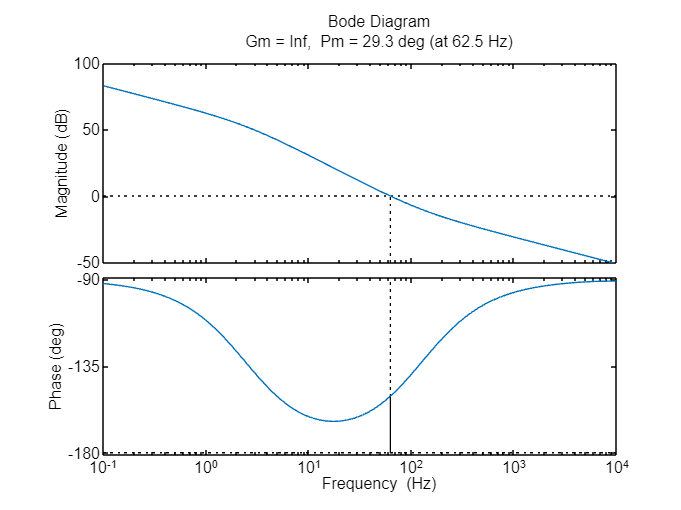

% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)  
G_cc = Kp_cc*(1+1/Ti_cc/s) ;%Kp_cc*(1 + s*Ti_cc)/(s*Ti_cc)

% Ki_cc = Kp_cc/Ti_cc
% 
% Kp_cc+Ki_cc/s

G_openl = G_cc*G_i;
margin(G_openl,options)

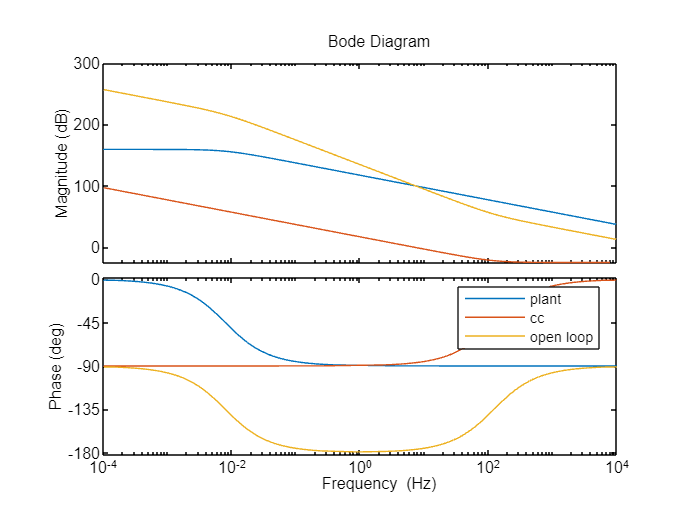



options = bodeoptions;
options.FreqUnits = 'Hz'; % or 'rad/second', 'rpm', etc.
options.PhaseWrapping='on';


bode(G_i,G_cc,G_openl, options)
legend('plant', 'cc','open loop')

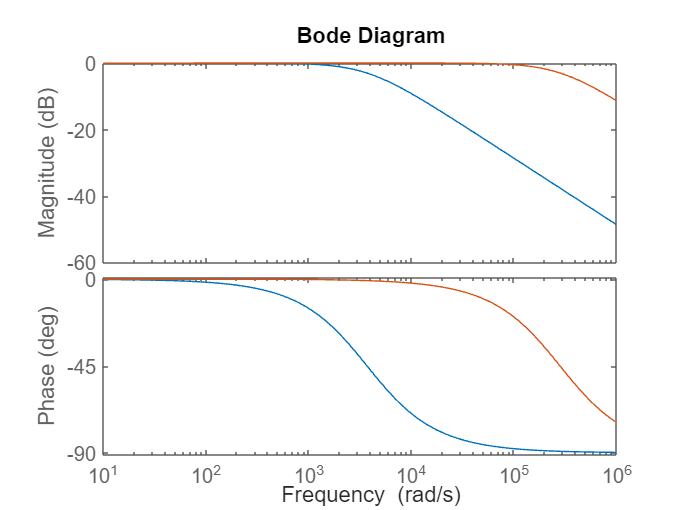

bode(Gapprox,G_i*G_cc/(1+G_i*G_cc),{10e-0,10e5})


% options.XLim = [10e-0,10e5];
% 
% margin(G_openl,options)
% margin(G_cl)
% step(G_cl)
% pzmap(G_cl)

T_ers = 1/(2*pi*f_c)

T_ers = 2.6975e-04

Gapprox = 1/(1+s*T_ers)

Gapprox =
 
         1
  ---------------
  0.0002698 s + 1
 
Continuous-time transfer function.
Model Properties



P0 = Sbase1

P0 = 420000000

p_1 = -1/T_ers

p_1 = -3.7071e+03

z_1 = 3*Vbase_lv^2/(2*L_f*P0)

z_1 = 4.4634e+03

UDC = V_dc

UDC = 1.1268e+03

UNd = Vbase_lv

UNd = 563.3826

C = C_f

C = 0.3189

L = L_f

L = 2.5397e-07

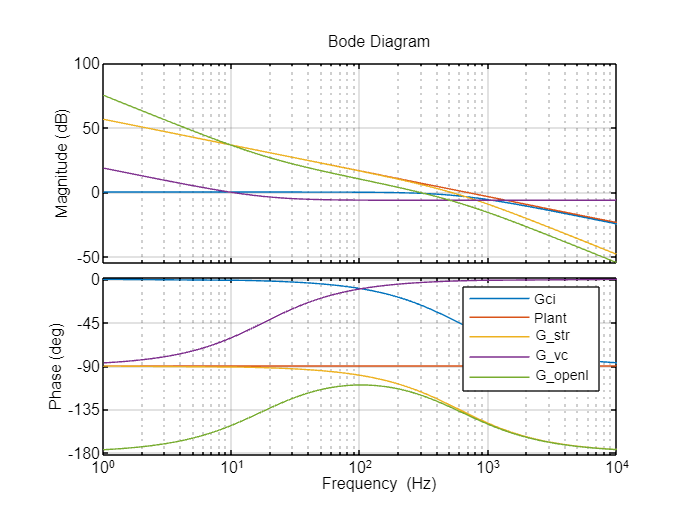


Gu=1/(s*c_f/omega_nom);%(3/2*UNd-s*L*P0/UNd)/(s*UDC*C);
Gstr=Gapprox*Gu;


kpu=0.479;
Tnu=0.009;
Gcu=kpu*(1+s*Tnu)/(s*Tnu);

Golu=Gcu*Gstr;
Gclu=Golu/(1+Golu); 

figure(3);
bode(Gapprox, Gu, Gstr,Gcu,Golu,options);
legend('Gci', 'Plant', 'G_{str}','G_{vc}','G_{openl}');
grid on;

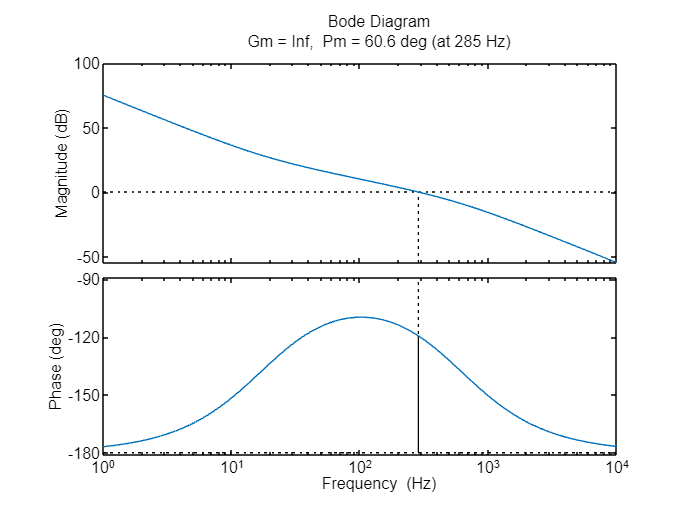

figure(4);
margin(Golu,options)

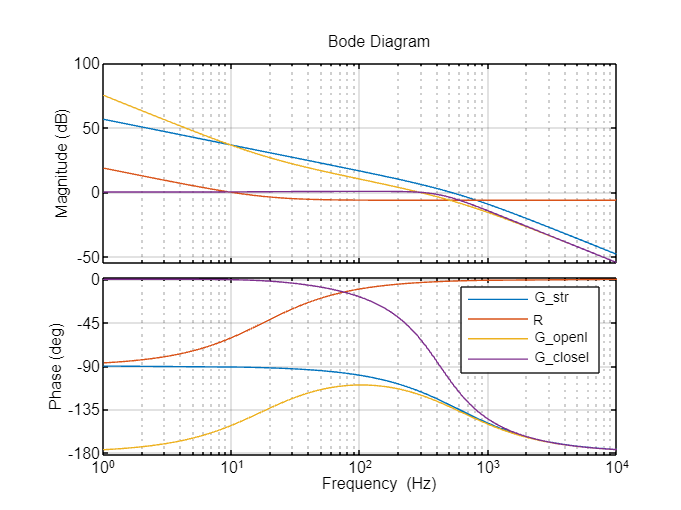

figure(5);
bode(Gstr,Gcu,Golu,Gclu,options);
legend('G_{str}','R','G_{openl}','G_{closel}');
grid on;

% 
% Kp_vc =  40 %C_f/Tau_cc % % 0.05%1/Vbase_lv;C_f*omega_v %
% Ki_vc =  200 % 2*Kp_vc*omega_v^2/omega_c% 2*Kp_vc*Tau_cc%    %1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 


% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
% G_vc = Kp_vc + Ki_vc/s
% 
% G_openl = G_vc*G_cc*G_plant
% G_cl = G_openl/(1+G_openl)

% bode(G_plant,G_cc,G_vc,G_openl,{10e-3,10e5})
% legend('plant', 'cc','vc','openl')
% 
% margin(G_vc)
% bode(G_vc,G_cc,{10e-3,10e5})
% 
% step(G_cl)
% pzmap(G_cl)



% asind((1-200*Tau_cc)/(1+200*Tau_cc))
% sqrt(Ki_vc*1/Tau_cc)
% ans*0.0757204
G_dc = 0.005*Sbase1*(1+0.005*1/s)

G_dc =
 
  2.1e06 s + 10500
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


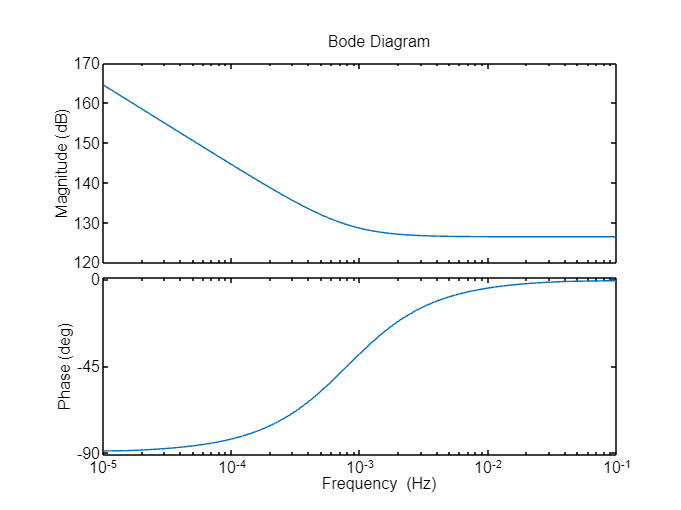

bode(G_dc,options)

% droop control

% (wmeas-wref)/(Pref-Pmeas) = kp_p

    % kp_p = (0.95-1)/(0.5-1)%0.05
    % 
    % % (vmeas-vref)/(Qref-Qmeas) = -kp_q
    % kp_q = (0.9-1)/(0-0.5)

% (5+0.4/s)/(1-5+0.4/s)
% 
% bode((5+0.4/s)/(1+5+0.4/s))
% 

% c_f=0.07
% H=omega_c/2
% tau_dcc = 2*L_f/3*Sbase1/Vbase_lv^2
% G_dc = -(2/C_f)*(tau_dcc*s+1)/s
% G_cc = 1/(0.005*s+1)
% K_v =C_f/2*H/s
% loop_gain = K_v*G_cc*G_dc
% bode(loop_gain)
% margin(H)
% loop_gain/(1-loop_gain)
% margin(loop_gain/(1-loop_gain))
% 
% 
% 1/0.005*2*pi

## dc

% 
% omega_dc = 2*pi*20
% R_dc = V_dc^2/Sbase1
% Kp_dcc = omega_dc*C_dc
% Ki_dcc = omega_dc       
% 
% 
options.PhaseWrapping='off';


% ti = 1/f_c
% f_dc = f_c/5
% f_dc*2*pi
% G_i_dc = (0.01*s+1)/(s*0.01)
% (1/0.01)/(1/0.01+s)
% tau_plant = 2/3*L_f*1*Sbase1/Vbase_lv^2
% G_p_dc = -(2/C_f)*(tau_plant*s+1)/s
% G_dc_plant = G_i_dc*G_p_dc
% ks = 225        
% ki = 1
% Gdc = -ks/s
% G_dc_openl = Gdc*G_dc_plant
% n0 = 1/(10^(-23/20))
% 
% a = 200
% p = sqrt(a)*2*pi*f_dc
% N = n0*(s+p/a)/(s+p)
% 
% bode(G_dc_plant,Gdc,G_dc_openl,options)
% legend('plant', 'dc_c','openl')
% bode(N,options)
% margin(N*G_dc_openl,options)
% N*G_dc